# DEM POV TOOL:

# WARNING: BENCHMARKING IN MATLAB LIVE SCRIPTS IS BAD PRACTICE. 

## CONSIDER THIS MORE OF A "PROOF OF CONCEPT" THAN AN ACTUAL REPRESENTATION OF THE QUALITY OF THESE MODELS

# FOR ACCURATE BENCHMARKS, SEE benchmark.m

## Initial Variables:

% Size of the DEM peaks model used
sizeDEM = 50;

% Choose Your Delaunay Tolerance!
point_tol = 0.1;  % ex: 0.5 means half the points are used

% Define player coordinates and FOV
player_coord = [10, 10, 0];
FOV = 25;

## DEM Debugging Method 

% Disable warnings
warning off; 

% Create a DEM of some size 
ZI = peaks(sizeDEM);

% Test-Plot of the Figure
figure(1); clf; 
tic; 
surf(ZI); 
toc;

Elapsed time is 0.022025 seconds.


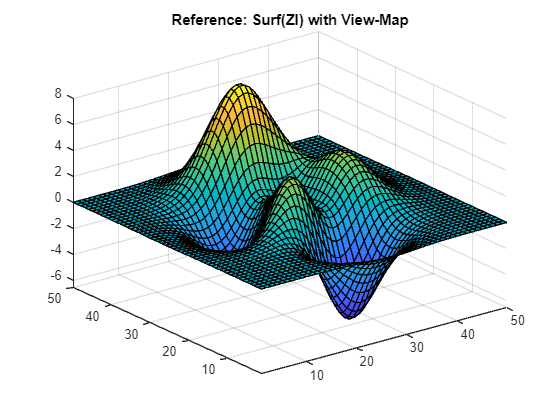


% Viewpoint Formatting
bounds = [-inf, inf];
xlim(bounds);
ylim(bounds);
zlim(bounds);

title('Reference: Surf(ZI) with View-Map');

## Delaunay: All The Points

% % Generate the peaks data
% ZI = peaks(sizeDEM);
% 
% % Create a grid of points
% [x, y] = meshgrid(1:size(ZI, 2), 1:size(ZI, 1));
% 
% % Create a matrix P containing the X and Y coordinates
% P = [x(:), y(:)];
% 
% % Create a triangulation using Delaunay from matrix P
% triangulation = delaunay(P(:, 1), P(:, 2));
% 
% % Plot the surface using trisurf
% figure(2); clf;
% tic;
% trisurf(triangulation, P(:, 1), P(:, 2), ZI(:));
% toc;
% 
% % Add labels and title
% xlabel('X');
% ylabel('Y');
% zlabel('Z');
% title('3D Surface Plot of ZI using Delaunay');


## Delaunay: Half The Points

% % Generate the peaks data
% ZI = peaks(sizeDEM);
% 
% % Create a grid of points
% [x, y] = meshgrid(1:size(ZI, 2), 1:size(ZI, 1));
% 
% % Create a matrix P containing the X and Y coordinates
% P = [x(:), y(:)];
% 
% % Calculate the number of points
% num_points = size(P, 1);
% 
% % Select every other point (triangulate half of the points)
% selected_indices = 1:2:num_points;
% selected_points = P(selected_indices, :);
% 
% % Create a triangulation using Delaunay from the selected points
% triangulation = delaunay(selected_points(:, 1), selected_points(:, 2));
% 
% % Plot the surface using trisurf
% figure(2); clf;
% tic;
% trisurf(triangulation, selected_points(:, 1), selected_points(:, 2), ZI(selected_indices));
% toc;
% 
% % Add labels and title
% xlabel('X');
% ylabel('Y');
% zlabel('Z');
% title('3D Surface Plot of ZI using Delaunay (Half the Points)');

## Delaunay: Choose Your Points!

% % Generate the peaks data
% ZI = peaks(sizeDEM);
% 
% % Create a grid of points
% [x, y] = meshgrid(1:size(ZI, 2), 1:size(ZI, 1));
% 
% % Create a matrix P containing the X and Y coordinates
% P = [x(:), y(:)];
% 
% % Calculate the number of points
% num_points = size(P, 1);
% 
% % Calculate the number of points to select based on point_tol
% num_points_to_select = round(point_tol * num_points);
% 
% % Randomly select the specified number of points
% selected_indices = randperm(num_points, num_points_to_select);
% selected_points = P(selected_indices, :);
% 
% % Create a triangulation using Delaunay from the selected points
% triangulation = delaunay(selected_points(:, 1), selected_points(:, 2));
% 
% % Plot the surface using trisurf
% figure(2); clf;
% tic;
% trisurf(triangulation, selected_points(:, 1), selected_points(:, 2), ZI(selected_indices));
% toc;
% 
% % Set axis limits
% xlim([0, sizeDEM]);
% ylim([0, sizeDEM]);
% zlim([min(ZI(:)), max(ZI(:))]);
% 
% % Add labels and title
% xlabel('X');
% ylabel('Y');
% zlabel('Z');
% title(['3D Surface Plot of ZI using Delaunay (', num2str(100*point_tol), '% of Points)']);


## Delaunay: Coords and FOV

% Generate the peaks data
ZI = peaks(sizeDEM);

% Create a grid of points
[x, y] = meshgrid(1:size(ZI, 2), 1:size(ZI, 1));

% Calculate the number of points
num_points = numel(x);

% Calculate the FOV boundaries
x_min = max(1, player_coord(1) - FOV);
x_max = min(sizeDEM, player_coord(1) + FOV);
y_min = max(1, player_coord(2) - FOV);
y_max = min(sizeDEM, player_coord(2) + FOV);
z_min = player_coord(3) - FOV;
z_max = player_coord(3) + FOV;

% Filter points based on FOV boundaries
valid_indices = find(x >= x_min & x <= x_max & y >= y_min & y <= y_max & ZI >= z_min & ZI <= z_max);
selected_points = [x(valid_indices), y(valid_indices)];
selected_ZI = ZI(valid_indices);

% Calculate the number of selected points based on the selected point_tol
selected_point_tol = point_tol * (numel(valid_indices) / num_points);
num_points_to_select = round(selected_point_tol * num_points);

% % Randomly select the specified number of points
% selected_indices = randperm(numel(valid_indices), num_points_to_select);
% selected_points = selected_points(selected_indices, :);
% selected_ZI = selected_ZI(selected_indices);

% Use vipmask to select points based on the threshold
thresh = selected_point_tol; % Use selected_point_tol as the threshold
keepcorners = true; % Set keepcorners to false

% Call the vipmask function to create a mask
[ZImask] = vipmask(selected_ZI, thresh, keepcorners);

% Use the mask to select the points
selected_points = selected_points(ZImask, :);
selected_ZI = selected_ZI(ZImask);


% Create a triangulation using Delaunay from the selected points
triangulation = delaunay(selected_points(:, 1), selected_points(:, 2));

% Plot the surface using trisurf
figure(2); clf; 
tic;
trisurf(triangulation, selected_points(:, 1), selected_points(:, 2), selected_ZI);
toc;

Elapsed time is 0.011855 seconds.


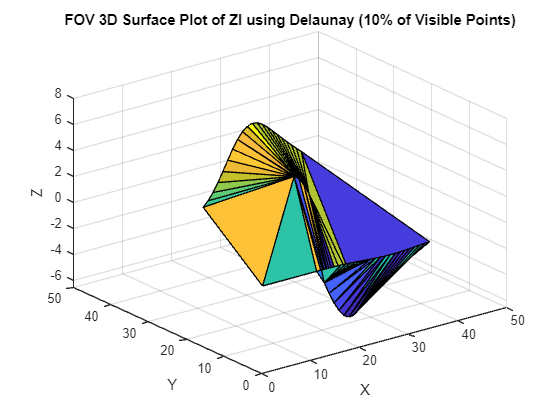


% Set axis limits (do not change xlim, ylim, or zlim)
hold off;
xlim([0, sizeDEM]);
ylim([0, sizeDEM]);
zlim([min(ZI(:)), max(ZI(:))]);

% Add labels and title
xlabel('X');
ylabel('Y');
zlabel('Z');
title(['FOV 3D Surface Plot of ZI using Delaunay (', num2str(100*point_tol), '% of Visible Points)']);

## Delaunay: Testing myPovTIN:

% Use MyTIN!
[tri, x, y, z] = myPovTIN(player_coord, FOV, ZI, point_tol);

% Plot the surface using trisurf
figure(2); clf;
tic;
trisurf(tri, x, y, z);
toc;

Elapsed time is 0.011450 seconds.


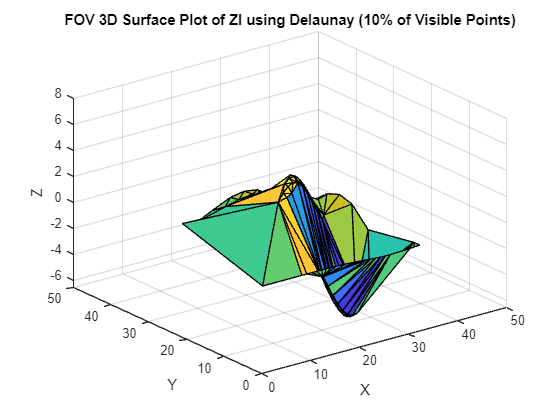


% Set axis limits (do not change xlim, ylim, or zlim)
xlim([0, sizeDEM]);
ylim([0, sizeDEM]);
zlim([min(ZI(:)), max(ZI(:))]);

% Add labels and title
xlabel('X');
ylabel('Y');
zlabel('Z');
title(['FOV 3D Surface Plot of ZI using Delaunay (', num2str(100*point_tol), '% of Visible Points)']);